### Load neural data

m1 = XZ135;
m2 = XZ138;
MName1 = m1.AnimalID;
MName2 = m2.AnimalID;
m1_neural = m1.MS{2}.FiltTraces(1801:end,logical(m1.MS{2}.goodCellVec)); % remove first 2 min
m2_neural = m2.MS{2}.FiltTraces(1801:end,logical(m2.MS{2}.goodCellVec));
m1_tstamp = m1.TimeStamp.Ts{2}.Ms(1801:end);
m2_tstamp = m2.TimeStamp.Ts{2}.Ms(1801:end);
m1_neural_bined = BinData(m1_neural, 5, 'mean'); % bin to 1/3 s
m2_neural_bined = BinData(m2_neural, 5, 'mean');
m1_tstamp_bined = BinData(m1_tstamp, 5, 'mean');
m2_tstamp_bined = BinData(m2_tstamp, 5, 'mean');

### Load tracking data

tracks_matrix_raw = h5read('PairQC7.h5','/tracks');
disp(size(tracks_matrix_raw))

       38643           5           2           2



% frames x nodes x 2 (x,y) x tracks
% nose earR earL tailbase body
% fill NAs
tracks_matrix_raw = fillmissing(tracks_matrix_raw, 'movmean', 7, 1);

### Read timestamp and bin data, trucate tracking to match length, align timestamp

tstamp_raw = csvread('PairQC7.csv', 1);
tstamp_raw = tstamp_raw(size(tstamp_raw,1)-size(tracks_matrix_raw,1)+1:end,2); % match video
% match neural data (remove first x minutes)
neural_starts_here = find(tstamp_raw>=m1_tstamp(1),1)

neural_starts_here = 3260

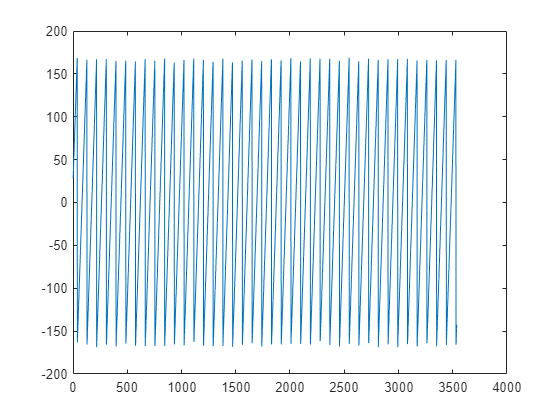

tracks_matrix = tracks_matrix_raw(neural_starts_here:end,:,:,:);
tstamp = tstamp_raw(neural_starts_here:end);

% bin Data
tracks_bined = BinData(tracks_matrix, 10, 'mean');
time_bined = BinData(tstamp, 10, 'mean');

% timestamp map
[idx1,idx2,tdifference] = TStampAlign(time_bined,m1_tstamp_bined);
figure, plot(tdifference);

if length(idx2) ~= length(idx1)
   idx1 = idx1(1:min(length(idx1), length(idx2)));
   idx2 = idx2(1:min(length(idx1), length(idx2)));
end
m1_tstamp_bined = m1_tstamp_bined(idx2,:);
m2_tstamp_bined = m2_tstamp_bined(idx2,:);
m1_neural_bined = m1_neural_bined(idx2,:);
m2_neural_bined = m2_neural_bined(idx2,:);
tracks_bined = tracks_bined(idx1,:,:,:);
time_bined = time_bined(idx1);


% find approximate head position by finding mid point between nose and body
head_coord = 1/2*(tracks_bined(:,1,:,:) + tracks_bined(:,5,:,:));

### Quadrant position states

qcenter = [289,253]; %[ycenter, xcenter]
qcode = [head_coord(:,:,1,1)<=qcenter(1), head_coord(:,:,2,1) > qcenter(2), head_coord(:,:,1,2)<=qcenter(1),...
    head_coord(:,:,2,2)>qcenter(2)];
qseries = [qcode(:,1)+qcode(:,2)*2,qcode(:,3)+qcode(:,4)*2];
qseries(qseries==1) = 4; qseries(qseries == 0) = 1;
q_diff = diff(qseries,[],2);
p_time_spent_together = sum(q_diff == 0)/length(q_diff)

p_time_spent_together = 0.2841

p_time_spent_neighbor = sum(or(abs(q_diff)==1,abs(q_diff)==3))/length(q_diff)

p_time_spent_neighbor = 0.4789

p_time_spent_diag = sum(abs(q_diff)==2)/length(q_diff)

p_time_spent_diag = 0.2369

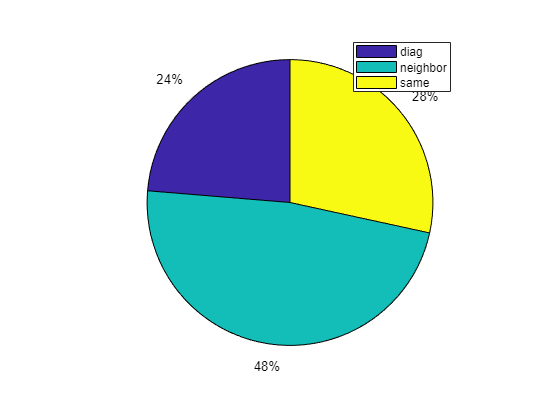

figure, pie([p_time_spent_diag,p_time_spent_neighbor,p_time_spent_together]);legend({'diag','neighbor','same'})

### Get PLSC and overlay plot with quadrant state

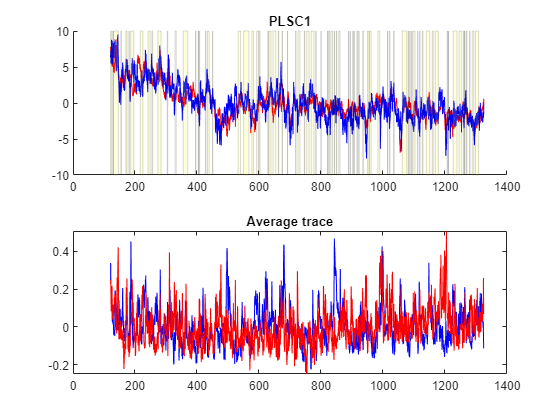

[PLS1, PLS2, USV] = GetPLSC(m1_neural, m2_neural);
figure, ax = subplot(2,1,1,'NextPlot','add'); plot(ax,m1_tstamp/1000,PLS1(:,1),'r'); plot(ax,m2_tstamp/1000,PLS2(:,1),'b')
% find same quadrant time point
same_q_t = find(qseries(:,1) == qseries(:,2));
% find consecutive bouts (apply threshold > )
onset_t = cat(1,1,find(diff(same_q_t)>2)+1);
offset_t = same_q_t([onset_t(2:end)-1;length(same_q_t)]);
onset_t = time_bined(same_q_t(onset_t))/1000;
offset_t = time_bined(offset_t)/1000;
% patch same quadrant period
for i = 1:length(onset_t)
    patch(ax,[onset_t(i),offset_t(i),offset_t(i),onset_t(i)],[ax.YLim(1),ax.YLim(1),ax.YLim(2),ax.YLim(2)],'y','FaceAlpha',0.15, 'EdgeAlpha',0.14);
end
title('PLSC1');
% plot average plot
subplot(2,1,2);plot(m1_tstamp_bined/1000, mean(m1_neural_bined,2),'b-'), hold on, plot(m2_tstamp_bined/1000, mean(m2_neural_bined,2),'r-');
title('Average trace');

### Prepare training/test set

S_idx = find(qseries(:,1) == qseries(:,2)); % same index
N_idx = find(or(abs(qseries(:,1)-qseries(:,2)) == 1, abs(qseries(:,1)-qseries(:,2)) == 3)); % neighbor index
D_idx = find(abs(qseries(:,1)-qseries(:,2)) == 2); % diagonal index
idxs = {S_idx,N_idx,D_idx};
state_names = {'Same','Neighbor','Diag'};
Y = zeros(length(idx2),1); Y(S_idx) = 1; Y(N_idx) = 2; Y(D_idx) = 3;
% prepare training/test set
m1_neural_bined = zscore(m1_neural_bined);
m2_neural_bined = zscore(m2_neural_bined);

### One vs all

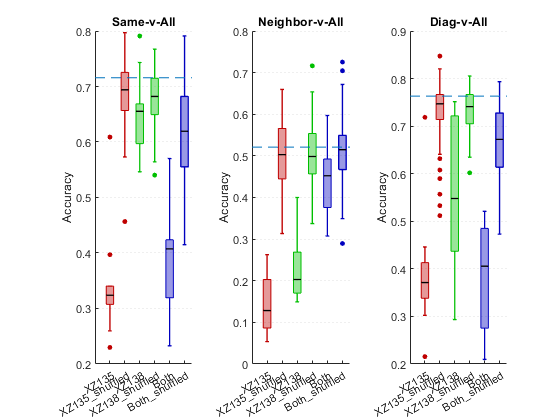

kfold = 10;
cvspace = 45;
f = figure;
for kd = 1:length(idxs)
    Y_temp = Y; Y_temp(cat(1,idxs{setdiff(1:length(idxs),kd)})) = 0; Y_temp(idxs{kd}) = 1;
%     part_temp = cvpartition(Y_temp, 'KFold', fold);
    [perform_1, perform_shifted_1] = OnevOneDecoder(m1_neural_bined, Y_temp, kfold, cvspace,'logistic','accuracy');
    [perform_2, perform_shifted_2] = OnevOneDecoder(m2_neural_bined, Y_temp, kfold, cvspace,'logistic','accuracy');
    [perform_3, perform_shifted_3] = OnevOneDecoder([m1_neural_bined,m2_neural_bined], Y_temp, kfold, cvspace,'logistic','accuracy');
    perform = [perform_1,perform_2,perform_3];
    perform_shifted = [perform_shifted_1, perform_shifted_2, perform_shifted_3];
    a = subplot(1,3,kd,'Parent',f);
    XZBoxPlot({perform, perform_shifted},[1,2,3,1,2,3],[1,3,5,2,4,6],...
        {MName1,MName2,'Both',[MName1,'\_shuffled'],[MName2,'\_shuffled'],'Both\_shuffled'},[],a);
     randguess_ = max([length(idxs{kd})/length(Y_temp),1-length(idxs{kd})/length(Y_temp)]);
     line(a, a.XLim, [randguess_, randguess_],'LineStyle','--');
     title([state_names{kd},'-v-All']); ylabel('Accuracy');
end

### One vs one

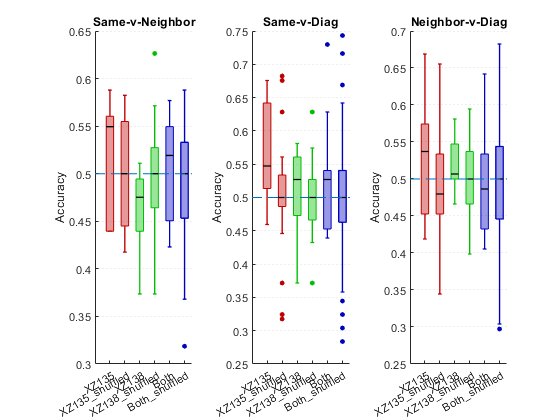

randguess_ = 0.5000

randguess_ = 0.5000

randguess_ = 0.5000

combines = nchoosek(1:3,2);
f = figure;
for kd = 1:size(combines,1)
    [mlen,midx] = min([length(idxs{combines(kd,1)}),length(idxs{combines(kd,2)})]);
    dsample_idx = datasample(idxs{setdiff(combines(kd,:),combines(kd,midx))}, mlen,'Replace',false);
    m1_neural_bined_dvn = m1_neural_bined(cat(1,idxs{combines(kd,midx)}, dsample_idx));
    m2_neural_bined_dvn = m2_neural_bined(cat(1,idxs{combines(kd,midx)}, dsample_idx));
    % same vs neighbor
    Y_temp = Y;Y_temp(idxs{combines(kd,1)}) = 1; Y_temp(idxs{combines(kd,2)}) = 0; Y_temp = Y_temp(cat(1,idxs{combines(kd,midx)}, dsample_idx));
%     part_temp = cvpartition(Y_temp, 'KFold', fold);
    perform = [];
    perform_shifted = [];
    [perform_1, perform_shifted_1] = OnevOneDecoder(m1_neural_bined_dvn, Y_temp, kfold, cvspace,'logistic','accuracy');
    [perform_2, perform_shifted_2] = OnevOneDecoder(m2_neural_bined_dvn, Y_temp, kfold, cvspace,'logistic','accuracy');
    [perform_3, perform_shifted_3] = OnevOneDecoder([m1_neural_bined_dvn,m2_neural_bined_dvn], Y_temp, kfold, cvspace,'logistic','accuracy');
    perform = [perform_1,perform_2,perform_3];
    perform_shifted = [perform_shifted_1, perform_shifted_2, perform_shifted_3];
    a = subplot(1,3,kd,'Parent',f);
    XZBoxPlot({perform, perform_shifted},[1,2,3,1,2,3],[1,3,5,2,4,6],...
        {MName1,MName2,'Both',[MName1,'\_shuffled'],[MName2,'\_shuffled'],'Both\_shuffled'},[],a);
%     randguess_ = max([length(idxs{combines(kd,1)})/length(Y_temp),1-length(idxs{combines(kd,1)})/length(Y_temp)]);
    randguess_ = 0.5;
    line(a, a.XLim, [randguess_, randguess_],'LineStyle','--');
    title([state_names{combines(kd,1)},'-v-',state_names{combines(kd,2)}]); ylabel('Accuracy');
end 

### Behavior

% count the number of same->neighbor and neighbor->same change for each
% construct group state vector 1=same 2=neighbor 3=diag
gqseries = zeros(size(qseries,1),1);
gqseries(idxs{1}) = 1; gqseries(idxs{2}) = 2; gqseries(idxs{3}) = 3; unique(gqseries)

ans =      1
     2
     3


[gonset, goffset] = FindConsecutiveOnsetOffset(gqseries);
transit_cell = {cell(1,2), cell(1,2)} % mouse1, mouse2, enter, exit

transit_cell = 1×2 cell array
    {1×2 cell}    {1×2 cell}


for i = 1:numel(gonset{1}) % for each same onset
    onset_t = gonset{1}(i);
    if onset_t == 1
        continue
    end
    menter = find(qseries(onset_t-1,:) ~= qseries(onset_t,:));
    for k = menter
        transit_cell{k}{1} = [transit_cell{k}{1}; gonset{1}(i)];
    end
    offset_t = goffset{1}(i);
    mexit = find(qseries(offset_t,:) ~= qseries(offset_t+1,:));
    for k = mexit
        transit_cell{k}{2} = [transit_cell{k}{2}; goffset{1}(i)];
    end
end
    